clearvars;

### Parameter initialization


frequency = 0.25e6; % Signal frequency in Hz
dimension = 2^7; % Computational grid x and y dimensions
spacing = 50e-3/dimension; % Spacing between each point of the grid
image_order = 1; % nr or image "steps"

p_source = [0,0]; % Source coordinates
p_receiver = [-8,8]; % Receiver coordinates
p_wall = []; % Wall - 2 Points = 1 wall

### Single point source to receiver - no walls - order 1

Filtering input signal...
  maximum frequency supported by kgrid: 439.04kHz (2 PPW)
  filter cutoff frequency: 292.6933kHz (3 PPW)
  computation complete.
Running k-Wave simulation...
  start time: 22-Oct-2021 08:23:50
  reference sound speed: 343m/s
  dt: 341.6545ns, t_end: 206.0177us, time steps: 604
  input grid size: 128 by 128 grid points (50 by 50mm)
  maximum supported frequency: 439.04kHz
  precomputation completed in 0.11035s
  starting time loop...
  estimated simulation time 9.4791s...


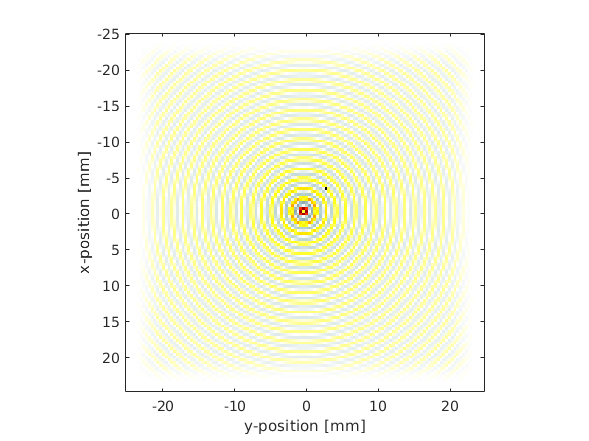

  simulation completed in 10.0248s
  total computation time 10.1772s


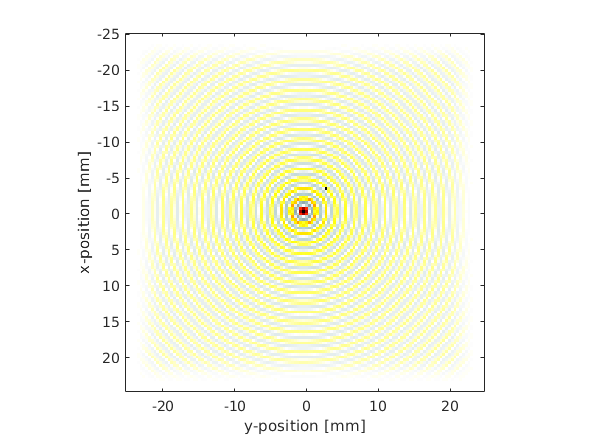

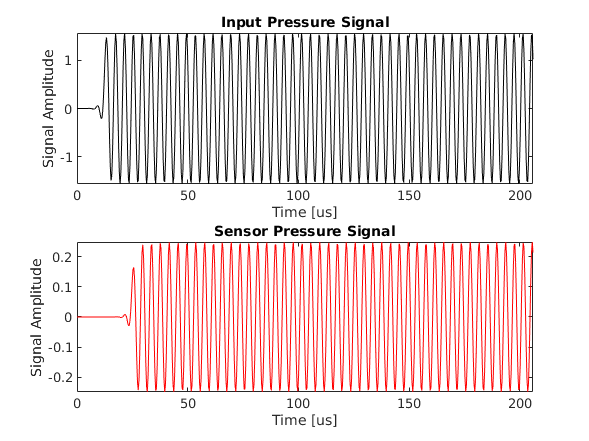

point_image_source(p_source, p_wall, image_order, p_receiver, frequency, dimension, spacing);

### Single point source to receiver - 1 wall - order 1

Filtering input signal...
  maximum frequency supported by kgrid: 878.08kHz (2 PPW)
  filter cutoff frequency: 585.3867kHz (3 PPW)
  computation complete.
Running k-Wave simulation...
  start time: 22-Oct-2021 08:06:46
  reference sound speed: 343m/s
  dt: 170.8273ns, t_end: 206.0177us, time steps: 1207
  input grid size: 256 by 256 grid points (50 by 50mm)
  maximum supported frequency: 878.08kHz
  precomputation completed in 0.058214s
  starting time loop...
  estimated simulation time 11.8622s...


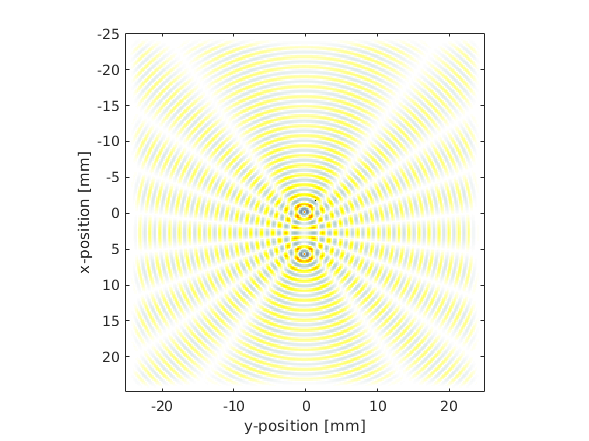

  simulation completed in 15.5866s
  total computation time 15.6731s


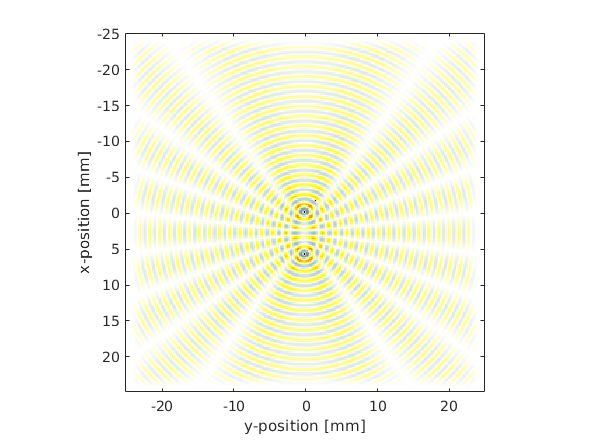

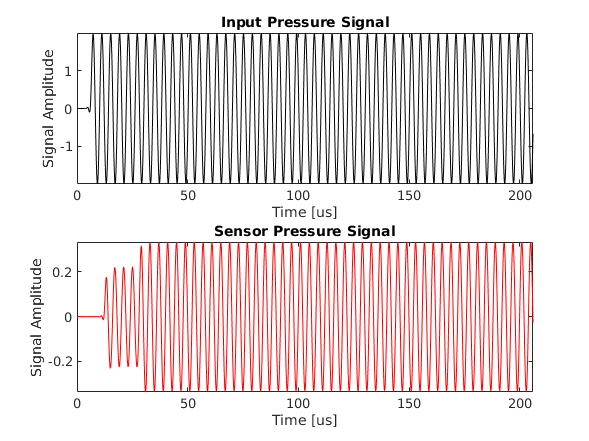

p_wall = [15 15 15 -15]; image_order = 1;
point_image_source(p_source, p_wall, image_order, p_receiver, frequency, dimension, spacing);

### Single point source to receiver - 2 walls - order 1

Filtering input signal...
  maximum frequency supported by kgrid: 878.08kHz (2 PPW)
  filter cutoff frequency: 585.3867kHz (3 PPW)
  computation complete.
Running k-Wave simulation...
  start time: 22-Oct-2021 08:08:01
  reference sound speed: 343m/s
  dt: 170.8273ns, t_end: 206.0177us, time steps: 1207
  input grid size: 256 by 256 grid points (50 by 50mm)
  maximum supported frequency: 878.08kHz
  precomputation completed in 0.06301s
  starting time loop...
  estimated simulation time 12.0517s...


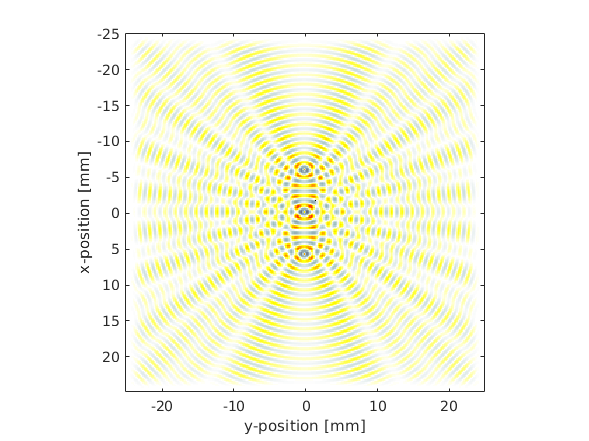

  simulation completed in 16.3867s
  total computation time 16.4802s


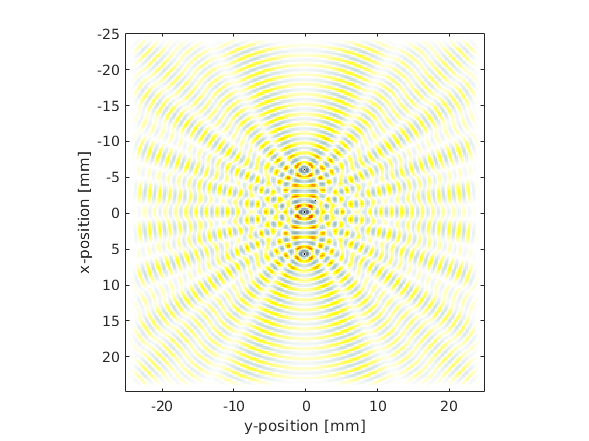

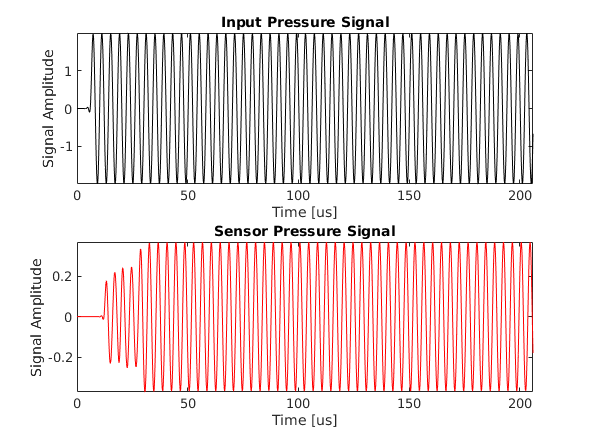

p_wall = [15 15 15 -15; -15 -15 -15 15]; image_order = 1;
point_image_source(p_source, p_wall, image_order, p_receiver, frequency, dimension, spacing);

### Single point source to receiver - 4 walls - order 1

Filtering input signal...
  maximum frequency supported by kgrid: 878.08kHz (2 PPW)
  filter cutoff frequency: 585.3867kHz (3 PPW)
  computation complete.
Running k-Wave simulation...
  start time: 22-Oct-2021 08:08:56
  reference sound speed: 343m/s
  dt: 170.8273ns, t_end: 206.0177us, time steps: 1207
  input grid size: 256 by 256 grid points (50 by 50mm)
  maximum supported frequency: 878.08kHz
  precomputation completed in 0.060286s
  starting time loop...
  estimated simulation time 12.3362s...


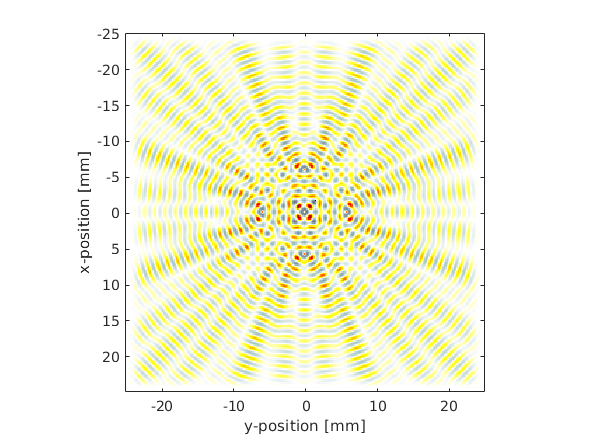

  simulation completed in 17.7501s
  total computation time 17.8365s


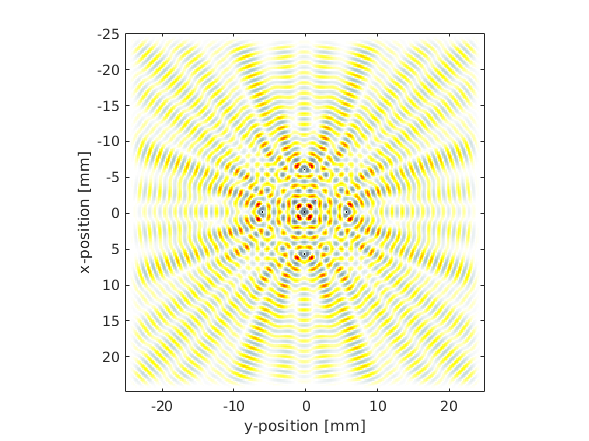

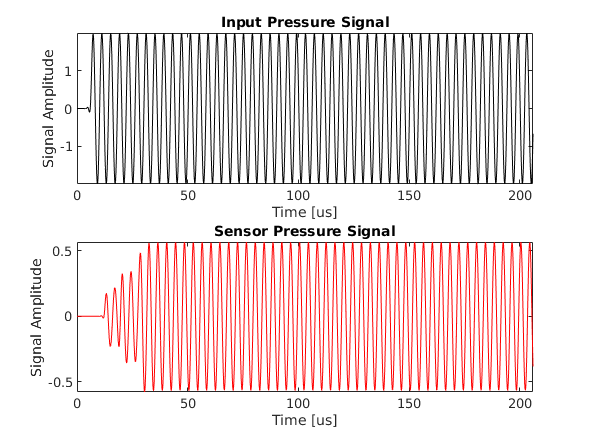

image_order = 1; p_wall = [15 15 15 -15; -15 -15 -15 15; -15 -15 15 -15; -15 15 15 15];
point_image_source(p_source, p_wall, image_order, p_receiver, frequency, dimension, spacing);

### Single point source to receiver - 4 walls - order 2

Filtering input signal...
  maximum frequency supported by kgrid: 878.08kHz (2 PPW)
  filter cutoff frequency: 585.3867kHz (3 PPW)
  computation complete.
Running k-Wave simulation...
  start time: 22-Oct-2021 08:12:16
  reference sound speed: 343m/s
  dt: 170.8273ns, t_end: 206.0177us, time steps: 1207
  input grid size: 256 by 256 grid points (50 by 50mm)
  maximum supported frequency: 878.08kHz
  precomputation completed in 0.056743s
  starting time loop...
  estimated simulation time 11.4993s...


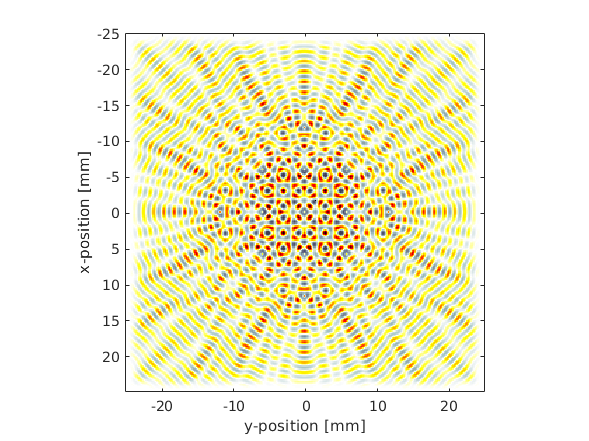

  simulation completed in 16.5315s
  total computation time 16.6146s


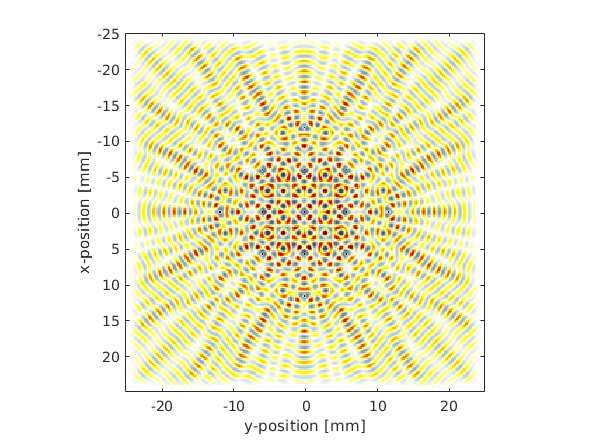

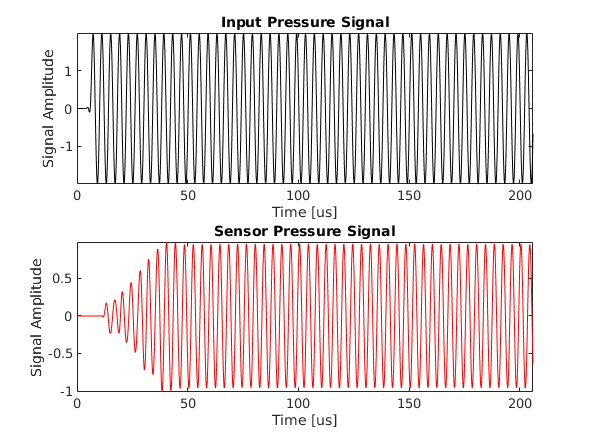

image_order = 2; p_wall = [15 15 15 -15; -15 -15 -15 15; -15 -15 15 -15; -15 15 15 15];
point_image_source(p_source, p_wall, image_order, p_receiver, frequency, dimension, spacing);

p_wall = [15 15 15 -15; -15 -15 -15 15; -15 -15 15 -15; -15 15 15 15];%[-20 -20 -20 20; -15 -15 15 -15;] ;%[20 20 20 -20; -20 -20 -20 20; -15 -15 15 -15; -15 15 15 15];%;-20 0 0 -20; 20 0 0 -20; -20 0 0 20];